A = pinholePattern(2000,100,0.1,100,100,1000)

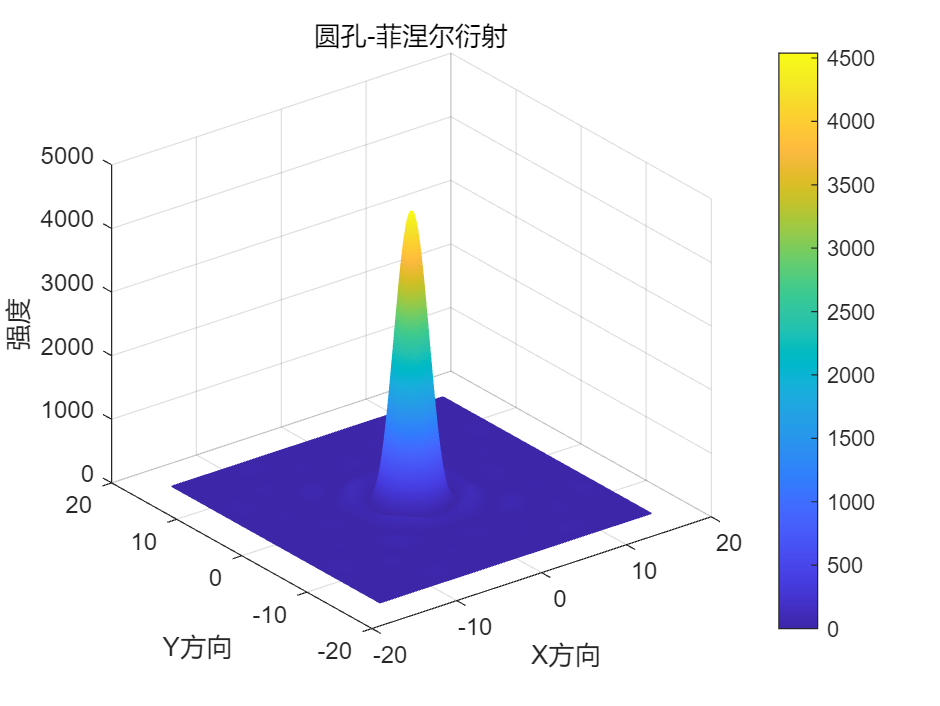


%% 夫琅禾夫衍射--圆孔
a=8.5*10^-2;%半径
lambda=632*10^(-9);%波长
z=a^(2)/lambda*100;%距离
N=16;%空间范围
L=512;%采样点
[x, y]=meshgrid(linspace(-N,N,L));%网格
%% 菲涅尔衍射-圆孔
%%  三维--快速傅里叶变换
figure()
z=a^(2)*pi/4/lambda*100;
z1=zeros(L,L);
z2=zeros(L,L);
for i =1:L
    for j =1:L
        if x(i,j)^2+y(i,j)^2<=a
            z1(i,j)=1;
            z2(i,j)=x(i,j)^2+y(i,j)^2;
        end 
    end
end
d=fftshift(abs((fft2(z1.*exp(1i*2*pi/lambda/2/z*z2))).^2));
i_2=d;
mesh(x,y,i_2);grid on;
zlabel('强度')
xlabel('X方向')
ylabel('Y方向')
title('圆孔-菲涅尔衍射')
colormap;
colorbar;

## --------------------------------------------------------------------------%%

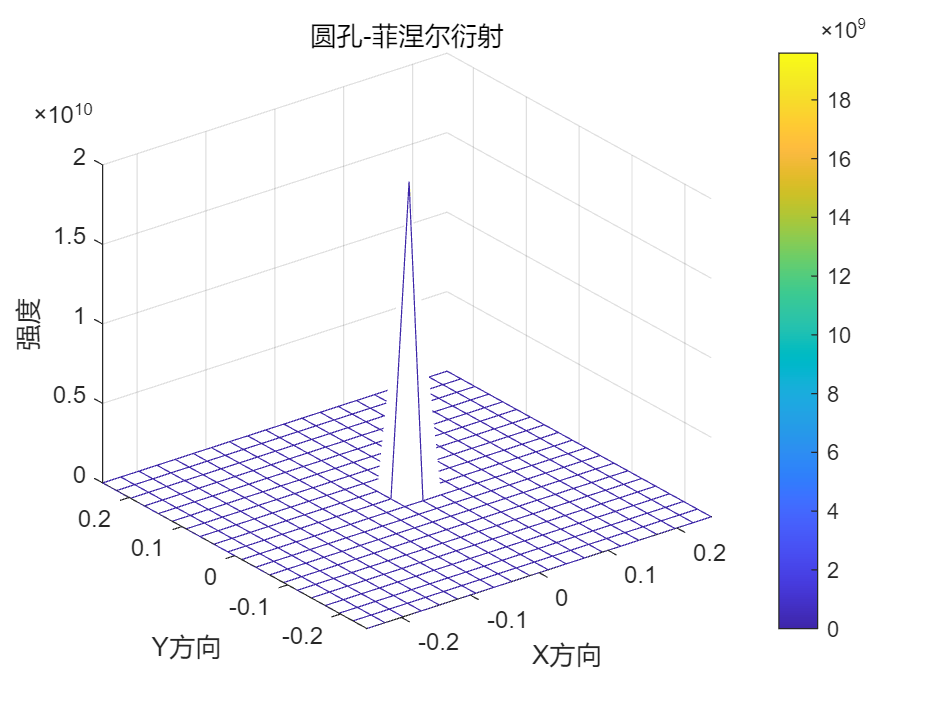

diffraction_pattern =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

% 调用和显示结果
lambda_nm = 550; % 波长，单位为nm
x = 100; % 点光源与小孔的水平距离，单位为mm
R = 0.1; % 小孔半径，单位为mm
d = 20; % 小孔到成像屏的距离，单位为mm
screen_size = 5; % 成像屏大小，单位为mm
num_points = 20; % 成像屏分辨率

diffraction_pattern = pinholePattern(lambda_nm, x, R, d, screen_size, num_points)